## Introduction to signal processing

### Part 1: Detecting PVC

**Specific objective:** To detect automatically these ectopic beats using normalized cross-correlation between the ECG signal and a “representative” ectopic beat pattern. When the resulting correlation is close to 1 --> PVC detected; otherwise, the beat is normal

**Materials****:**

- ECG signal with PVC (*ecgpvc.mat*)

- Fs = 200 Hz

- Duration: 250 seconds

- Matlab function *visualpvc*: to plot the ECG along time. It creates 5 subplots of 10 seconds each, thus 50 seconds of the signal can be observed in the figure

#### Procedure:

**1. Visualize the ECG using *****visualpvc.***

clear all;
clc;

load("ecgpvc.mat");
ecg= ecgpvc;

%ecg plot
%visualpvc(ecg);

**2. Create the representative ectopic beat using the average of the 5 first ectopic ones.**

The R-wave times of the first five PVCs (2.665, 6.355, 12.655, 21.41 and 22.69 s) were selected manually by inspecting the ECG with `visualpvc`, and converted to samples. 

Fs = 200; % sampling frequency

PVC = [2.665, 6.355, 12.655, 21.41, 22.69]; % exact time (R waves)
PVC_samples = round(PVC*Fs); % time to samples 

**2.1. Use the R wave (where the maximum value appears) of the ectopic beat to obtain the time when they appear.**

A fixed window of 80 samples before and 120 after each R wave (0.4 s and 0.6 s) was extracted, so each segment includes the P and T waves. 

% time window
before = 80;
after = 120;  

beats= [];

for i = 1:5
    beats(:,i) = ecg(PVC_samples(i)-before : PVC_samples(i)+ after);
end

**2.2 Use a fixed time window around the R wave including P and T waves. All segments or time windows should be averaged in order to get a representative beat.**

The five segments were averaged to obtain the representative PVC beat.

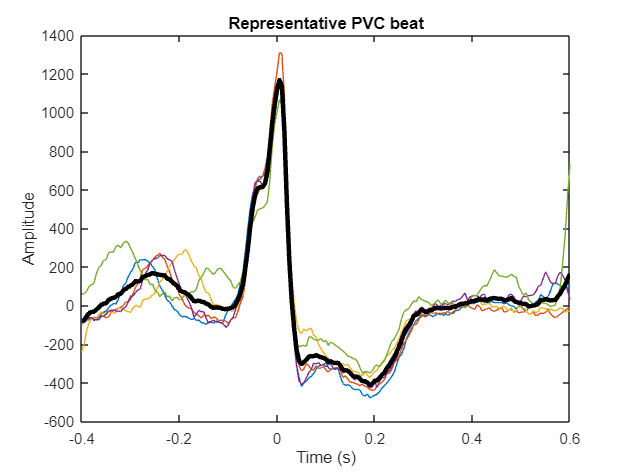

averagePVC = mean(beats,2);

t = (-before:after)/Fs;

figure;
plot(t, beats);
hold on;
plot(t, averagePVC, 'k', 'LineWidth', 3);
xlabel('Time (s)')
ylabel('Amplitude')
title('Representative PVC beat')

The five PVCs (coloured) are aligned at the R wave (t = 0 s) and overlap closely around the QRS and the wide negative T wave. The average (black) is therefore a good template, given that differences appear only at the edges of the window, due to noise and neighbouring beats.

**3. Use *****xcorr***** function between the ECG and the average ectopic beat to distinguish ectopic from normal beat*. You should establish a threshold for this purpose.**

The normalized cross-correlation between the ECG and the average PVC was computed with `xcorr(...,'coeff')`, sliding a window of the template’s length and keeping the zero-lag value. The result is aligned to the R wave. A threshold of 0.6 and a minimum peak distance of 0.5 s (`findpeaks`) were used to detect PVCs.

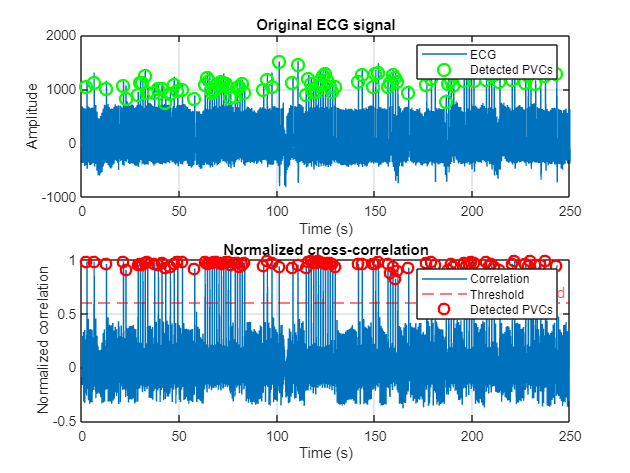

% length of the PVC beat
N = length(averagePVC);
correlation = zeros(1, length(ecg)-N+1);

% calculate normalized cross-correlation using a sliding window
for i = 1:length(ecg)-N+1

    % ECG segment with the same length as the representative beat
    window = ecg(i:i+N-1);

    % normalized cross-correlation
    [c, lags] = xcorr(window, averagePVC, 'coeff');

    % take the value corresponding to zero lag
    correlation(i) = c(lags == 0);

end

% time corresponding to the beginning of each sliding window
t_corr = (0:length(correlation)-1)/Fs;

% the R wave is 'before' samples after the beginning of the window.
t_R = t_corr + before/Fs;

threshold = 0.6;

[pks,locs] = findpeaks(correlation, ...
    'MinPeakHeight', threshold, ...
    'MinPeakDistance', 0.5*Fs);

detectedPVC = t_R(locs);

detected_samples = round(detectedPVC * Fs);
detected_samples = detected_samples(detected_samples >= 1 & detected_samples <= length(ecg));

t = (0:length(ecg)-1)'/Fs;

figure
% ECG signal 
subplot(2,1,1)
plot(t,ecg)
hold on

% mark the five PVCs used to create the representative beat
plot(detected_samples/Fs, ecg(detected_samples), 'go','MarkerSize',8,'LineWidth',1.5)
xlabel('Time (s)')
ylabel('Amplitude')
title('Original ECG signal')
grid on

legend('ECG','Detected PVCs')


% normalized correlation
subplot(2,1,2)

plot(t_R,correlation)
hold on

yline(threshold,'r--','Threshold')

plot(detectedPVC,pks,'ro','MarkerSize',7,'LineWidth',1.5)

xlabel('Time (s)')
ylabel('Normalized correlation')
title('Normalized cross-correlation')
grid on
linkaxes(findobj(gcf,'Type','axes'),'x');
legend('Correlation','Threshold','Detected PVCs')

Top: the ECG with the detected PVCs marked (green). Bottom: the normalized correlation. Normal beats and noise stay below 0.5, while PVCs reach 0.8–1, since they match the template. The threshold of 0.6 separates both groups well.

### Part 2: Filtering ECG

**Aim****: **To analyze an ECG signal in time and frequency domains before and after appropriate filtering

**Materials****:**

- ECG signal: *ecgf.mat*

- Fs = 1 kHz

#### Procedure:

**1. Load the signal and plot it, showing that it seems to have noise at high frequencies that need to be filtered**

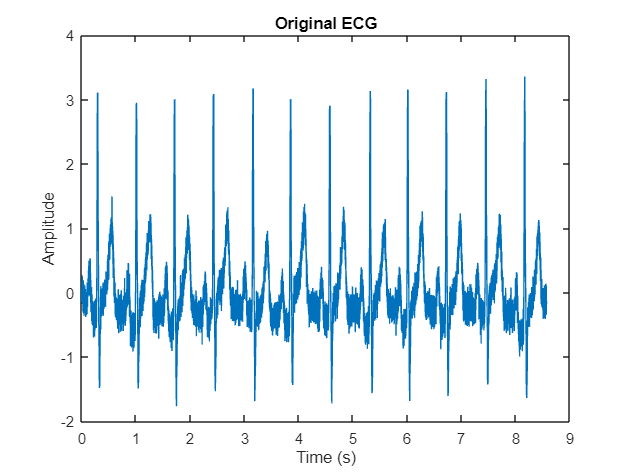

load("ecgf.mat");
Fs2 = 1000; %sampling frequency

t = (0:length(ecgf)-1)/Fs2;

figure
plot(t,ecgf)

xlabel('Time (s)')
ylabel('Amplitude')
title('Original ECG')

The ECG `ecgf.mat` (Fs = 1 kHz) is plotted against time. The P, QRS and T waves are clearly visible, but the signal has fast fluctuations superimposed on it, especially in the isoelectric segments between beats. This points to high-frequency noise, so filtering is needed

**2. Decide the type and the cut-off frequency of the filter based on the PSD (compute the DFT/FFT with Hanning or Hamming window). By observing the PSD decide what kind of noise the signal has and which type of Butterworth filter you suggest. Use the 4th order.**

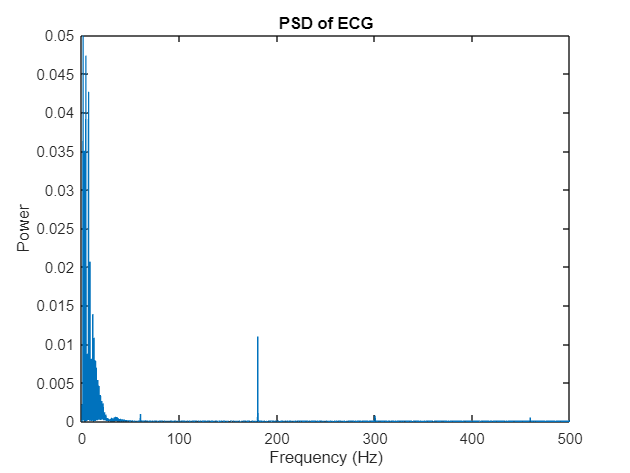

N = length(ecgf);

% hamming window
w = hamming(N);

% FFT
Y = fft(ecgf.*w);

% PSD
PSD = (1/(Fs2*N)) * abs(Y).^2;

% frequency axis
f = (0:N-1)*(Fs2/N);

% keep only frequencies from 0 to 500 Hz
half = 1:floor(N/2);

figure
plot(f(half),PSD(half))

xlabel('Frequency (Hz)')
ylabel('Power')
title('PSD of ECG')

xlim([0 500])

The PSD was computed with the FFT and a Hamming window. Most of the power is below ≈40 Hz (ECG content). Above that, there is a narrow peak at 180 Hz (plus small ones at 60 and 300 Hz), which is noise. Since the noise lies well above the ECG band, the simplest effective option is a 4th-order low-pass Butterworth filter with fc = 40 Hz.

fc = 40;

[b,a] = butter(4,fc/(Fs2/2),'low');

ecgff = filtfilt(b,a,ecgf);

The signal was filtered with a 4th-order low-pass Butterworth (fc = 40 Hz) using `filtfilt`. The filter removes the high-frequency noise while preserving the ECG morphology.

**3. Compare the time and DFT signals before and after filtering by plotting them. Comment the effectiveness of the filter. The signal is named *****ecgff.*** 

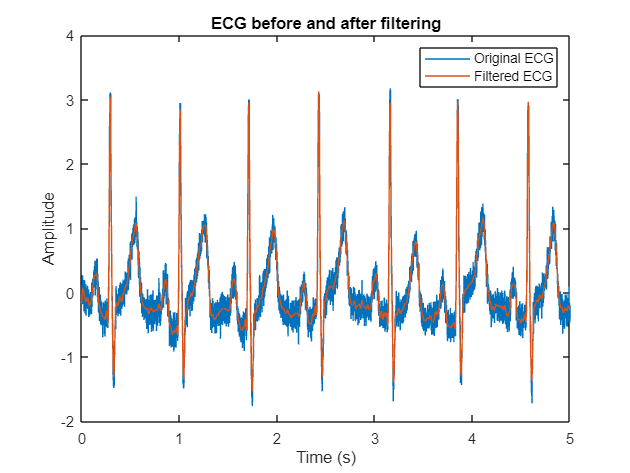

% time domain
figure
plot(t,ecgf)
hold on
plot(t,ecgff)

xlabel('Time (s)')
ylabel('Amplitude')
title('ECG before and after filtering')
legend('Original ECG','Filtered ECG')

xlim([0 5])

The filtered ECG (orange) follows the original (blue) but without the fast fluctuations. P, QRS and T waves keep their shape, amplitude and timing, and the QRS peaks are not attenuated.

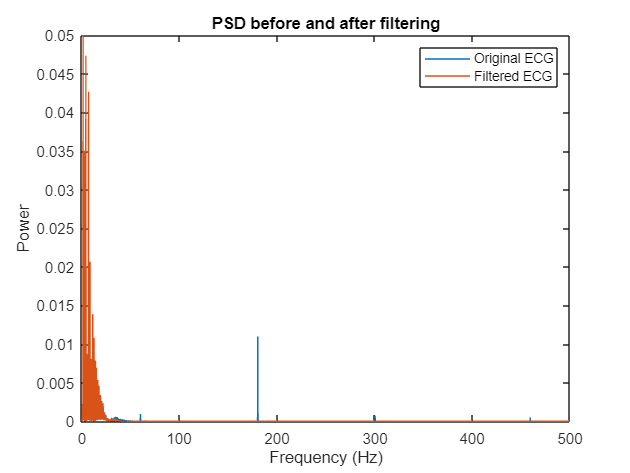

% frequency domain
Y_original = fft(ecgf.*w);
Y_filtered = fft(ecgff.*w);

PSD_original = (1/(Fs2*N))*abs(Y_original).^2;
PSD_filtered = (1/(Fs2*N))*abs(Y_filtered).^2;

figure
plot(f(half),PSD_original(half))
hold on
plot(f(half),PSD_filtered(half))

xlabel('Frequency (Hz)')
ylabel('Power')
title('PSD before and after filtering')
legend('Original ECG','Filtered ECG')

xlim([0 500])

The 180 Hz peak (and the 60 and 300 Hz ones) present in the original disappears after filtering. The low-frequency content (<40 Hz), where the ECG power lies, is unchanged. Therefore, the filter is effective.

**4. Filter the T waves. Compute the PSD for ecgff and decide the type of filter and cut-off frequency to attenuate the T wave preserving as much as possible the other waves, particularly the QRS complex (see slide 17 section 1.4 from Chapter 1 presentation). Filter the signal (4th order Butterworth) and overlap in the same figure the ecgff and the signal resulting from this filtering. Compare also the PSD to verify the filtering effect. Show and comment if T waves are the most filtered ones.**

The PSD of `ecgff` shows the strongest components below 8 Hz, where the T wave lies, while the QRS extends to higher frequencies (10–25 Hz). A 4th-order high-pass Butterworth filter with fc = 8 Hz was therefore applied (`filtfilt`) to attenuate the T wave while preserving the QRS.

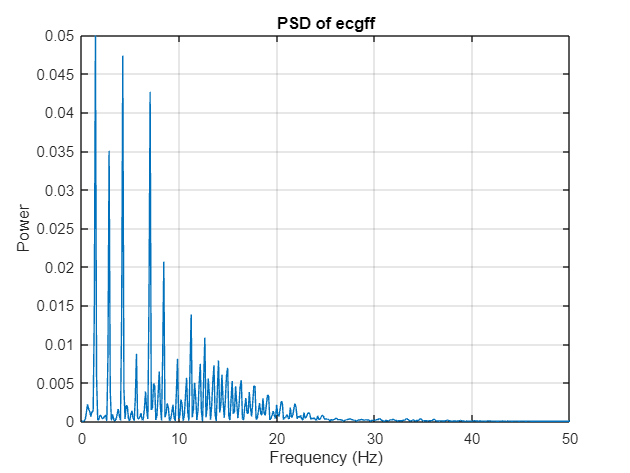

Y_ecgff = fft(ecgff .* w); 
PSD_ecgff = (1/(Fs2*N)) * abs(Y_ecgff).^2; 
figure 
plot(f(half), PSD_ecgff(half)) 
xlabel('Frequency (Hz)') 
ylabel('Power') 
title('PSD of ecgff') 
xlim([0 50]) 
grid on

Power is concentrated in discrete peaks (1.4, 2.8, 4.2, 7 Hz...) that decay with frequency and become negligible above ≈25 Hz. The peaks below 8 Hz carry the T and P waves.

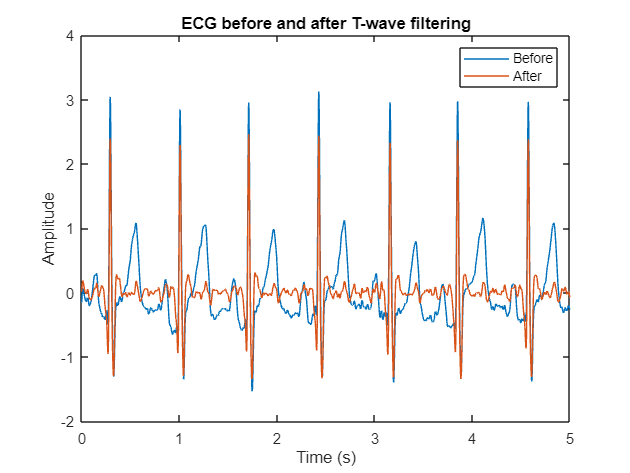

fc_T = 8;

[bT,aT] = butter(4,fc_T/(Fs2/2),'high');

ecg_Tfiltered = filtfilt(bT,aT,ecgff);

% compare signals in time domain
figure
plot(t,ecgff)
hold on
plot(t,ecg_Tfiltered)

xlabel('Time (s)')
ylabel('Amplitude')
title('ECG before and after T-wave filtering')
legend('Before','After')
xlim([0 5])

After filtering (orange), the T waves almost disappear and the baseline is flat, while the QRS complexes remain clear. Their amplitude is somewhat reduced (3 → 2.4), so the QRS is preserved but not perfectly.

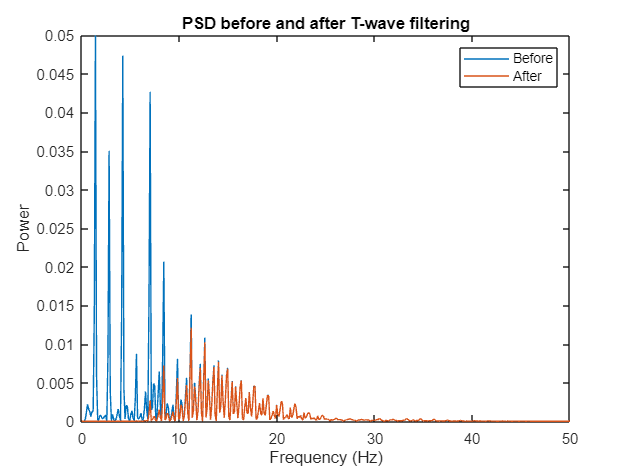

% compare PSD
Y_Tfiltered = fft(ecg_Tfiltered.*w);
PSD_Tfiltered = (1/(Fs2*N)) * abs(Y_Tfiltered).^2;

figure
plot(f(half),PSD_ecgff(half))
hold on
plot(f(half),PSD_Tfiltered(half))

xlabel('Frequency (Hz)')
ylabel('Power')
title('PSD before and after T-wave filtering')
legend('Before','After')
xlim([0 50])

The components below 8 Hz are removed, while the content above 10 Hz is unchanged. This confirms that the T wave (and P wave and baseline) are the most filtered, and the QRS is the main component that remains.

**5. Apply the same filter to ecgff using two approaches: passing it twice and only once. Compare in two figures overlapping both filtered signals and their PSD. Comment and show the effect of the phase of this IIR filter. **

The 4th-order high-pass IIR filter was applied once and twice in the same direction using `filter`. Since the filter has a non-linear phase, the waves are delayed and distorted. Applying it twice doubles this effect and also gives a stronger attenuation below the cut-off frequency.

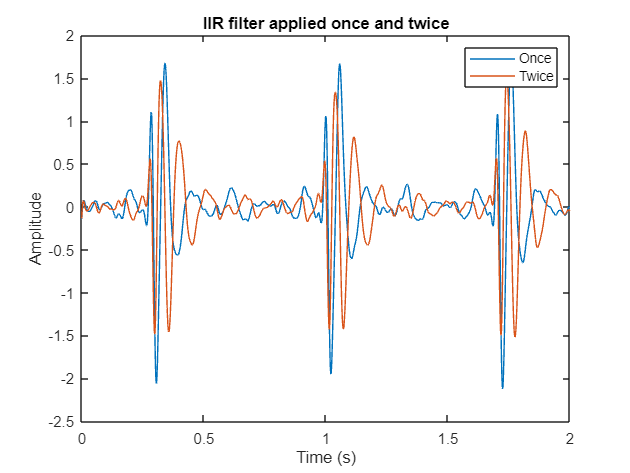

% apply the IIR filter once
ecg_once = filter(bT,aT,ecgff);

% apply the same filter a second time
ecg_twice = filter(bT,aT,ecg_once);

% compare both signals in time domain
figure
plot(t,ecg_once)
hold on
plot(t,ecg_twice)

xlabel('Time (s)')
ylabel('Amplitude')
title('IIR filter applied once and twice')
legend('Once','Twice')

xlim([0 2])

The filtered ECG is shifted to the right with respect to the original QRS position, and the shape is distorted (the QRS looks split into several lobes). The twice-filtered signal (orange) is shifted and distorted even more than the once-filtered one (blue).

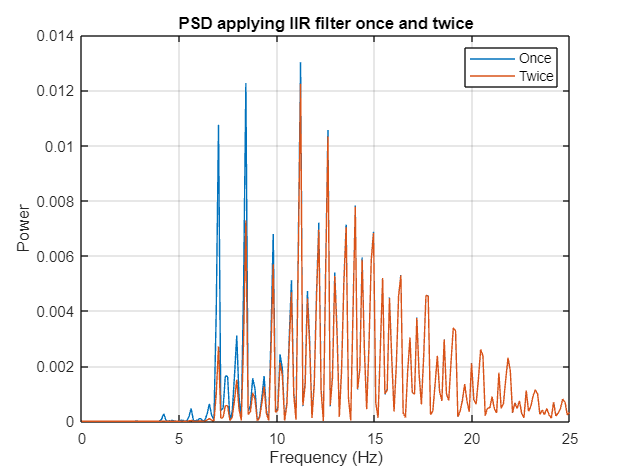

% calculate PSD of both signals
Y_once = fft(ecg_once.*w);
Y_twice = fft(ecg_twice.*w);

PSD_once = (1/(Fs2*N)) * abs(Y_once).^2; 
PSD_twice = (1/(Fs2*N)) * abs(Y_twice).^2;

figure
plot(f(half),PSD_once(half))
hold on
plot(f(half),PSD_twice(half))

xlabel('Frequency (Hz)')
ylabel('Power')
title('PSD applying IIR filter once and twice')
legend('Once','Twice')

xlim([0 25])
grid on

Both signals are almost zero below 6 Hz and similar above 10 Hz. Around the cut-off (7–9 Hz) the twice-filtered signal (orange) has lower peaks, so the attenuation is stronger. The PSD only shows the magnitude, so the phase effect is visible only in the time plot.When the filter is applied twice using `filter`, the phase distortion is applied twice and therefore the temporal distortion is increased. The PSD shows a stronger attenuation of the low-frequency components after the second filtering pass.

**6. Apply a FIR filter (4th order) to ecgff to evaluate its efficiency to attenuate T waves. Compare the resulting signal with the filtered one obtained two points above when using the IIR filter. Increase the order of the FIR filter and find the appropriate one to obtain a similar attenuation of T waves found with the IIR filter.**

The 4th order FIR filter is first tested. We used the same cut-off frequency as the IIR filter.

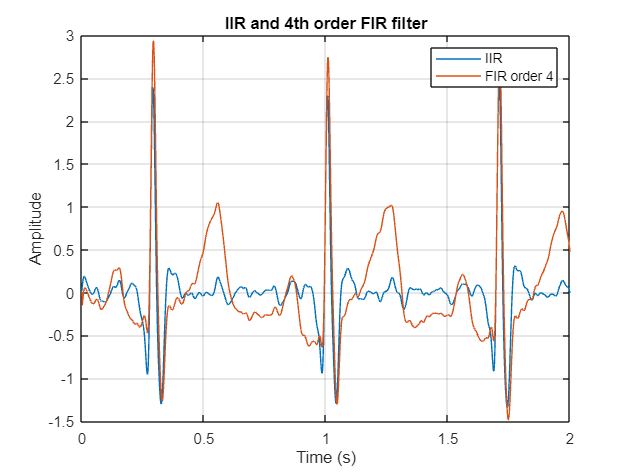

bFIR4 = fir1(4,fc_T/(Fs2/2),'high');

ecg_FIR4 = filter(bFIR4,1,ecgff);

% compare IIR and FIR (4th order) in time domain
figure
plot(t,ecg_Tfiltered)
hold on
plot(t,ecg_FIR4)

xlabel('Time (s)')
ylabel('Amplitude')
title('IIR and 4th order FIR filter')
legend('IIR','FIR order 4')

xlim([0 2])
grid on

In the time-domain graph, the 4th-order FIR filter still shows large T waves between the QRS complexes, while the IIR filter attenuates them much more. The QRS complexes remain visible in both signals. This suggests that the 4th-order FIR filter is not attenuating the low-frequency components sufficiently. To confirm this, we compare the PSD of both filtered signals in the frequency domain.

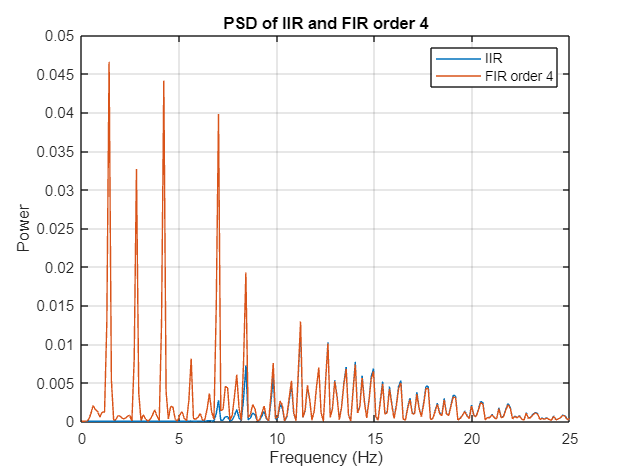

% PSD of IIR
Y_IIR = fft(ecg_Tfiltered.*w);
PSD_IIR = (1/(Fs2*N))*abs(Y_IIR).^2;

% PSD of FIR (4th order)
Y_FIR4 = fft(ecg_FIR4.*w);
PSD_FIR4 = (1/(Fs2*N))*abs(Y_FIR4).^2;

% compare PSD
figure
plot(f(half),PSD_IIR(half))
hold on
plot(f(half),PSD_FIR4(half))

xlabel('Frequency (Hz)')
ylabel('Power')
title('PSD of IIR and FIR order 4')
legend('IIR','FIR order 4')

xlim([0 25])
grid on

The PSD confirms this observation. The 4th-order FIR filter retains much more power at low frequencies than the IIR filter. Since the T wave is mainly associated with low-frequency content, this indicates that the FIR filter does not attenuate the T wave enough. Therefore, the FIR order is increased to obtain a sharper frequency response and a result closer to the IIR filter.

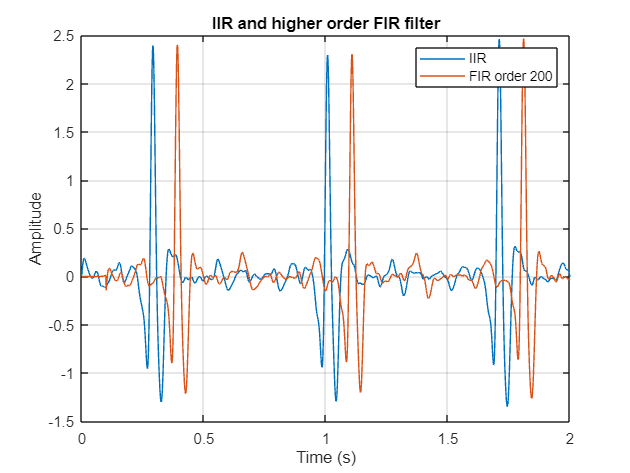

% test a higher-order FIR filter
order_FIR = 200;

bFIR_high = fir1(order_FIR,fc_T/(Fs2/2),'high');

ecg_FIR_high = filter(bFIR_high,1,ecgff);

% compare IIR and higher FIR order in time domain
figure
plot(t,ecg_Tfiltered)
hold on
plot(t,ecg_FIR_high)

xlabel('Time (s)')
ylabel('Amplitude')
title('IIR and higher order FIR filter')
legend('IIR','FIR order 200')

xlim([0 2])
grid on

After increasing the FIR order to 200, the FIR signal becomes much more similar to the IIR-filtered signal. The large T waves that were still visible with the 4th-order FIR are now strongly attenuated, while the QRS complexes are preserved. However, the FIR signal is shifted in time with respect to the IIR signal. This happens because the high-order FIR filter introduces a larger delay.

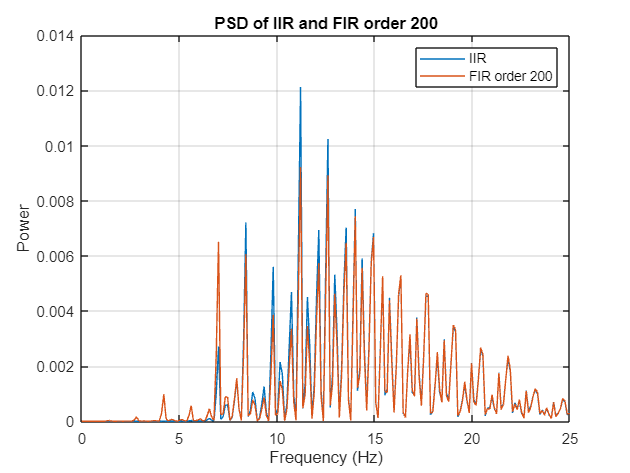

% PSD of higher order FIR
Y_FIR_high = fft(ecg_FIR_high.*w);
PSD_FIR_high = (1/(Fs2*N)) * abs(Y_FIR_high).^2;

% compare PSD
figure
plot(f(half),PSD_IIR(half))
hold on
plot(f(half),PSD_FIR_high(half))

xlabel('Frequency (Hz)')
ylabel('Power')
title('PSD of IIR and FIR order 200')
legend('IIR','FIR order 200')

xlim([0 25])
grid on

The PSD shows that the 200th-order FIR filter now produces a frequency response much closer to the IIR filter. In particular, the low-frequency power has been strongly reduced compared with the 4th-order FIR case, which means that the T-wave frequency components are now much better attenuated. At higher frequencies, both filters preserve similar components associated mainly with the QRS complex.

In conclusion, increasing the FIR order improves T-wave attenuation and makes its response more similar to the IIR filter, but at the cost of a larger delay and a much higher filter order.